**Clearing Console**

clear; 
close all; 
clc;

**Creating an Image Datastore**

datapathTrain='C:\Users\Lance\Documents\MATLAB\Pneumonia Detection\Dataset\train';

imds=imageDatastore(datapathTrain, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
% imds.ReadFcn = @preprocess_with_resize;

**Creating an Image Datastore with the Post Training Test Dataset **

datapathValidation='C:\Users\Lance\Documents\MATLAB\Pneumonia Detection\Dataset\validation';

imdsTesting=imageDatastore(datapathValidation, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
imdsTesting.ReadFcn = @preprocess_with_resize;

imdsTesting299=imageDatastore(datapathValidation, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
imdsTesting299.ReadFcn = @preprocess_with_resize299;

totalTesting=countEachLabel(imdsTesting);

**Oversampling Image Datastore for Training and Validation Datasets**

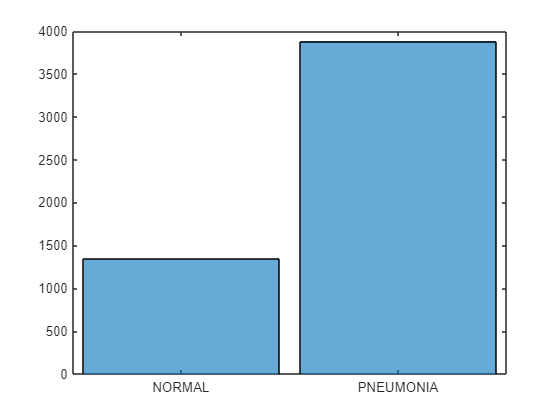

histogram(imds.Labels);

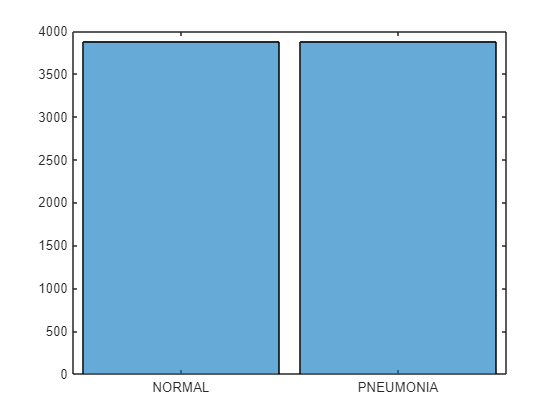

% Storing the count of each class to a 2x1 categorical array
labels=imds.Labels;
[G,classes] = findgroups(labels);
numObservations = splitapply(@numel,labels,G);

% Finding the largest class (to use it as the oversampling ceiling)
desiredNumObservationsPerClass = max(numObservations);

files = splitapply(@(x){rand_replicate_files(x,desiredNumObservationsPerClass)},imds.Files,G);
files = vertcat(files{:});
labels = [];
info=strfind(files,'\');

% Adding labels to replicated files (using folder names)
for i = 1:numel(files)
    idx = info{i};
    dirName = files{i};
    targetStr = dirName(idx(end-1)+1:idx(end)-1);
    targetStr2 = cellstr(targetStr);
    labels = [labels;categorical(targetStr2)];
end

imds.Files = files;
imds.Labels = labels;
% labelCount_oversampled = countEachLabel(imds_Train)
histogram(imds.Labels);

**Split ImageDatastore to Training and Validation Dataset and Modify ReadFcn**

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8);

imdsTrain.ReadFcn = @preprocess_with_resize;
imdsValidation.ReadFcn = @preprocess_with_resize;

totalTrain=countEachLabel(imdsTrain);
totalValidation=countEachLabel(imdsValidation);

**Data Augmentation**

augmenter = imageDataAugmenter( ...
    'RandRotation',[-10,10], ...
    'RandScale',[0.85,1], ...
    'RandXTranslation',[-15,15]);

auimdsTrain = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
auimdsValidation = augmentedImageDatastore([224 224],imdsValidation,'DataAugmentation',augmenter);
% auimdsTesting = augmentedImageDatastore([224 224],imdsTesting);

**Cleaning Workspace**

% clearvars -except auimdsTrain auimdsValidation imdsTrain imdsValidation imdsTesting imdsTesting299;

**Load Neural Network (Optional)**

load('ResNet50.mat');
load('DenseNet201.mat');
load('Xception.mat');
% load('MobileNetV2.mat');
load('ResNet101.mat');

**Test Neural Network**

[ResNet50YPred,ResNet50probabilities] = classify(ResNet50,imdsTesting);
[DenseNet201YPred,DenseNet201probabilities] = classify(DenseNet201,imdsTesting);
[XceptionYPred,Xceptionprobabilities] = classify(Xception,imdsTesting299,'ExecutionEnvironment','cpu');
% [MobileNetV2YPred,MobileNetV2probabilities] = classify(MobileNetV2,imdsTesting);
[ResNet101YPred,ResNet101probabilities] = classify(ResNet101,imdsTesting);

**Prepare Ensemble Array for Testing**

outputResNet50Array = categorical(zeros(624,2)); % Pre-allocating Matrix for Efficiency
for i = 1:1:624
    if isequal(ResNet50YPred(i),"NORMAL")
        outputResNet50Array(i,1) = string(ResNet50YPred(i));
        outputResNet50Array(i,2) = string(ResNet50probabilities(i,1));
    elseif isequal(ResNet50YPred(i),"PNEUMONIA")
        outputResNet50Array(i,1) = string(ResNet50YPred(i));
        outputResNet50Array(i,2) = string(ResNet50probabilities(i,2));
    end
end
clear i;

outputDenseNet201Array = categorical(zeros(624,2)); % Pre-allocating Matrix for Efficiency
for i = 1:1:624
    if isequal(DenseNet201YPred(i),"NORMAL")
        outputDenseNet201Array(i,1) = string(DenseNet201YPred(i));
        outputDenseNet201Array(i,2) = string(DenseNet201probabilities(i,1));
    elseif isequal(DenseNet201YPred(i),"PNEUMONIA")
        outputDenseNet201Array(i,1) = string(DenseNet201YPred(i));
        outputDenseNet201Array(i,2) = string(DenseNet201probabilities(i,2));
    end
end
clear i;

outputXceptionArray = categorical(zeros(624,2)); % Pre-allocating Matrix for Efficiency
for i = 1:1:624
    if isequal(XceptionYPred(i),"NORMAL")
        outputXceptionArray(i,1) = string(XceptionYPred(i));
        outputXceptionArray(i,2) = string(Xceptionprobabilities(i,1));
    elseif isequal(XceptionYPred(i),"PNEUMONIA")
        outputXceptionArray(i,1) = string(XceptionYPred(i));
        outputXceptionArray(i,2) = string(Xceptionprobabilities(i,2));
    end
end
clear i;

% outputMobileNetV2Array = categorical(zeros(624,2)); % Pre-allocating Matrix for Efficiency
% for i = 1:1:624
%     if isequal(MobileNetV2YPred(i),"NORMAL")
%         outputMobileNetV2Array(i,1) = string(MobileNetV2YPred(i));
%         outputMobileNetV2Array(i,2) = string(MobileNetV2probabilities(i,1));
%     elseif isequal(MobileNetV2YPred(i),"PNEUMONIA")
%         outputMobileNetV2Array(i,1) = string(MobileNetV2YPred(i));
%         outputMobileNetV2Array(i,2) = string(MobileNetV2probabilities(i,2));
%     end
% end
% clear i;

outputResNet101Array = categorical(zeros(624,2)); % Pre-allocating Matrix for Efficiency
for i = 1:1:624
    if isequal(ResNet101YPred(i),"NORMAL")
        outputResNet101Array(i,1) = string(ResNet101YPred(i));
        outputResNet101Array(i,2) = string(ResNet101probabilities(i,1));
    elseif isequal(ResNet101YPred(i),"PNEUMONIA")
        outputResNet101Array(i,1) = string(ResNet101YPred(i));
        outputResNet101Array(i,2) = string(ResNet101probabilities(i,2));
    end
end
clear i;

**Ensemble Network Process**

YPred = categorical(zeros(624,1));

for i = 1:1:624
    probabilityMatrix = string([outputResNet50Array(i,1), outputResNet50Array(i,2); ...
                         outputDenseNet201Array(i,1), outputDenseNet201Array(i,2); ...
                         outputXceptionArray(i,1), outputXceptionArray(i,2); ...
                         outputResNet101Array(i,1), outputResNet101Array(i,2)]);
    
    normalProbabilityScore = 0;
    normalProbabilityCount = 0;
    pneumoniaProbabilityScore = 0;
    pneumoniaProbabilityCount = 0;
    
    for index = 1:1:4
       if isequal(probabilityMatrix(index,1),"NORMAL")
           normalProbabilityCount = normalProbabilityCount + 1;
           normalProbabilityScore = str2double(probabilityMatrix(index,2)) + normalProbabilityScore;
       elseif isequal(probabilityMatrix(index,1),"PNEUMONIA")
           pneumoniaProbabilityCount = pneumoniaProbabilityCount + 1;
           pneumoniaProbabilityScore = str2double(probabilityMatrix(index,2)) + pneumoniaProbabilityScore;
       end
    end
    
    normalProbabilityTotal = normalProbabilityScore / normalProbabilityCount;
    pneumoniaProbabilityTotal = pneumoniaProbabilityScore / pneumoniaProbabilityCount;
    
    % Probability Average Classification
    if (normalProbabilityTotal > pneumoniaProbabilityTotal || isnan(pneumoniaProbabilityTotal))
       YPred(i) = "NORMAL";
    elseif (pneumoniaProbabilityTotal > normalProbabilityTotal || isnan(normalProbabilityTotal))
       YPred(i) = "PNEUMONIA";
    elseif (normalProbabilityTotal == pneumoniaProbabilityTotal)
       YPred(i) = "INCONCLUSIVE";
    else
       fprintf('Error');
    end
    clear normalProbabilityTotal pneumoniaProbabilityTotal probabilityMatrix;
end

**Confusion Matrix and Statistics on Trained Neural Network [TN,FP,FN,TP]**

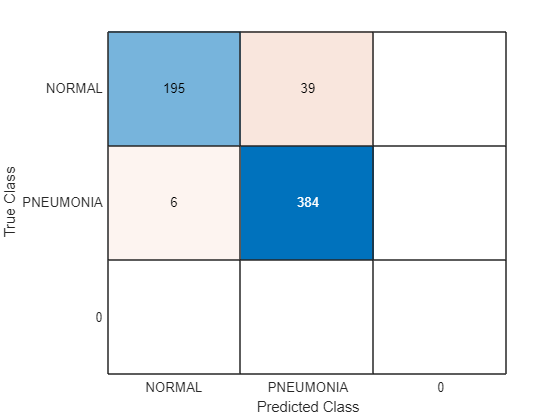

% confusionMatrix = confusionmat(imdsTesting.Labels,YPred);
confusionMatrixStats = confusionmatStats(imdsTesting.Labels,YPred);
%%confusionchart(True_Labels, Predicted_Lables)
confusionchart(imdsTesting.Labels,YPred); 

TN = confusionMatrixStats.confusionMat(1);
TP = confusionMatrixStats.confusionMat(5);
FN = confusionMatrixStats.confusionMat(2);
FP = confusionMatrixStats.confusionMat(4);

MCC = (TP*TN-FP*FN)/sqrt((TP+FP)*(TP+FN)*(TN+FP)*(TN+FN));

clear TN TP FN FP;